## PRE-PROCESSING

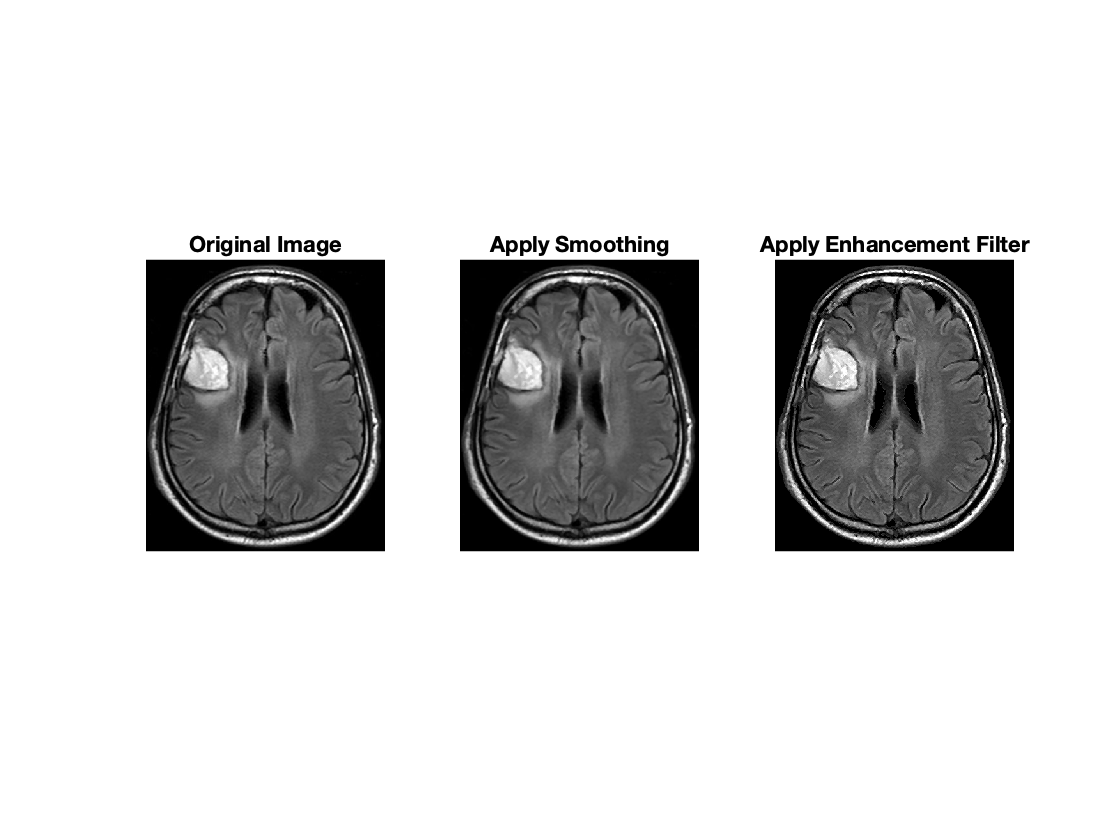

% read image + grayscale
img = imread("dataset/Y6.jpg");
[row, col, depth] = size(img);
if (depth == 3)
    img = rgb2gray(img);
end
figure,
subplot(1,3,1), imshow(img), title('Original Image');

% smoothing
img = medfilt2(img, [3 3]);
subplot(1,3,2), imshow(img), title('Apply Smoothing');

% remove white blobs with centroids which are within 10% of the edge
% to remove texts or other noise
img = remove_edge_blobs(img);

% enhancement filter
kernel = [0 -1  0; -1  5 -1; 0 -1  0];
img = imfilter(img, kernel);
subplot(1,3,3), imshow(img), title('Apply Enhancement Filter');

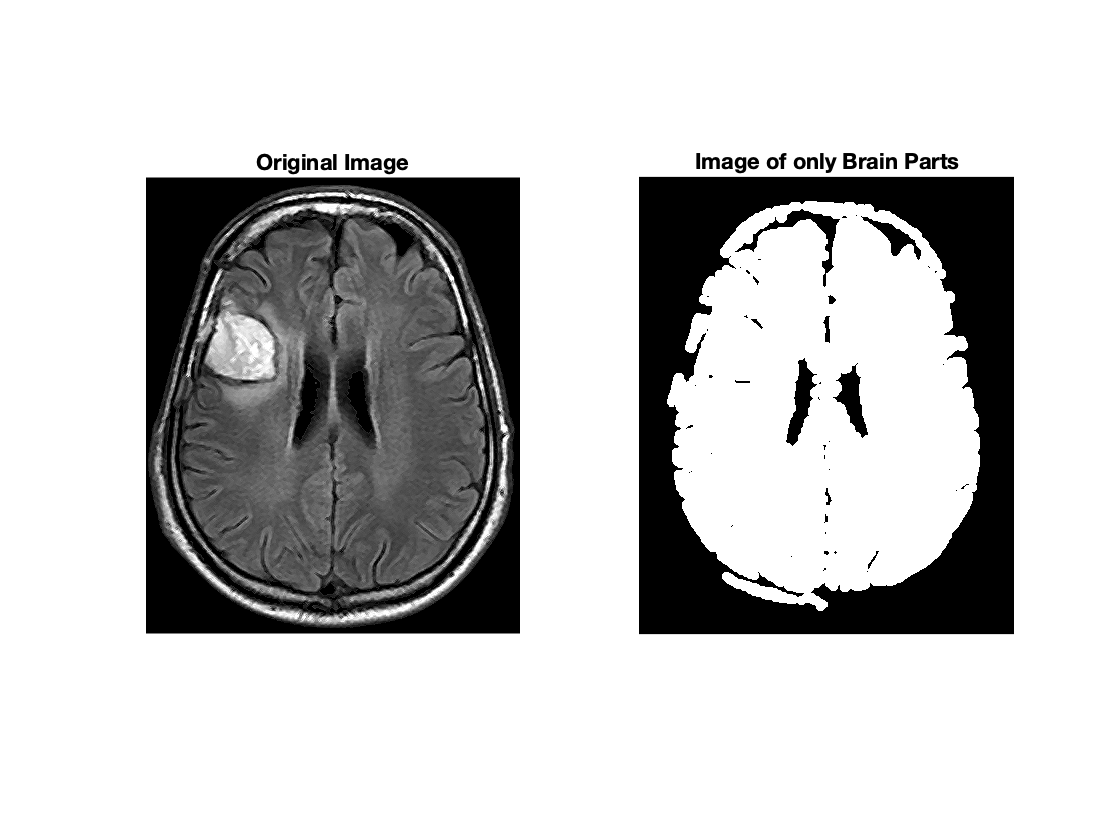

% adaptive histogram equalisation
hist_img = adapthisteq(img);

% skull stripping - connected regions
starting_threshold = 0.02;
[cr_img, auto_threshold] = auto_strip_skull(hist_img, starting_threshold);
figure,
subplot(1,2,1), imshow(img), title("Original Image");
subplot(1,2,2), imshow(cr_img), title("Image of only Brain Parts");

disp("The current threshold automatically set to " + auto_threshold);

The current threshold automatically set to 0.04


Change the value of the threshold if the results of skull stripping are undesirable. Lower the threshold to cover more area and vice versa. 

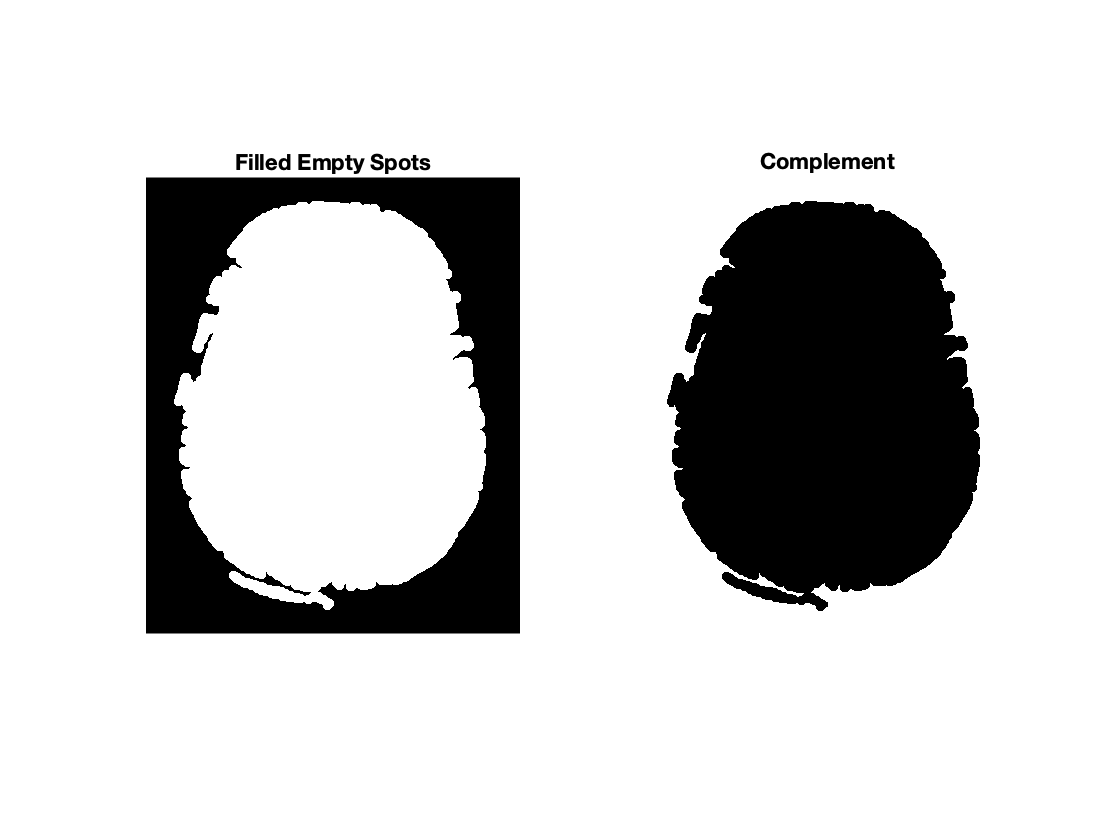

threshold = 0;
if threshold ~= 0
    cr_img = strip_skull(hist_img, threshold);
    subplot(1,2,2), imshow(cr_img), title("Image of only Brain Parts");
end

filled = imfill(cr_img, "holes");
figure,
subplot(1,2,1), imshow(filled), title("Filled Empty Spots");
subplot(1,2,2), imshow(~filled), title("Complement");

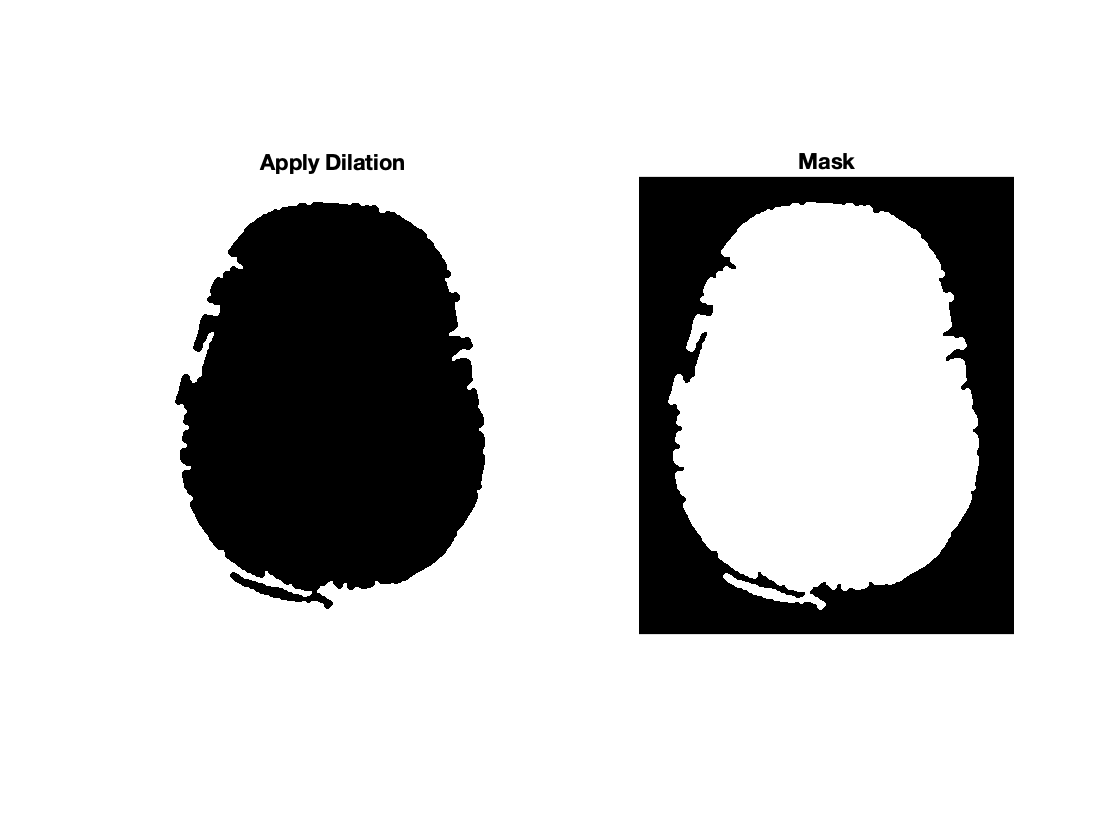

% skull stripping - dilation
dilation_se = strel("square", 3);
dilated = imdilate(~filled, dilation_se);
mask = ~dilated;
figure,
subplot(1,2,1),imshow(dilated),title("Apply Dilation");
subplot(1,2,2),imshow(mask),title("Mask");

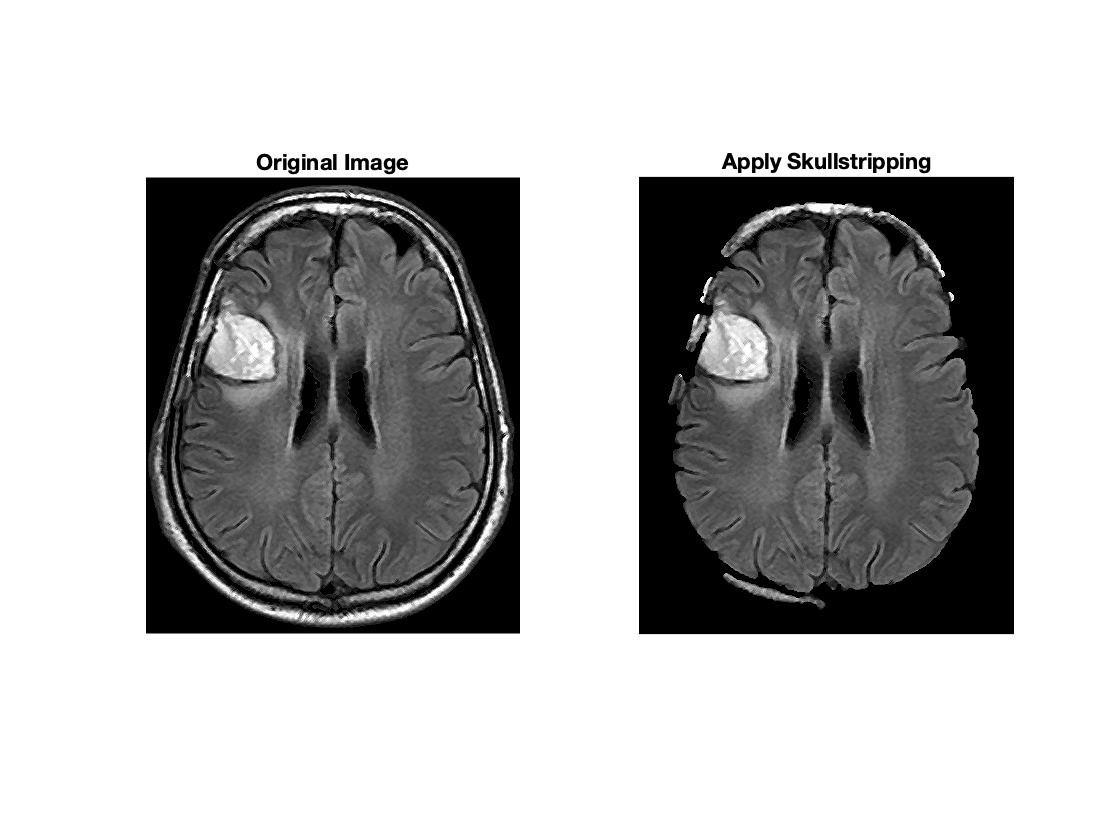

% final results of skull stripping
ss_img = img .* uint8(mask);
figure,
subplot(1,2,1), imshow(img), title("Original Image");
subplot(1,2,2), imshow(ss_img), title("Apply Skullstripping");

## SEGMENTATION OF TUMOURS

### Otsu's Thresholding

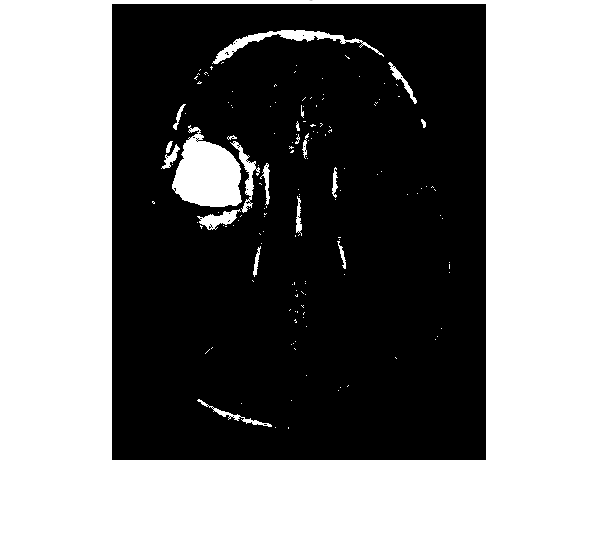

[otsu_img, auto_levels] = auto_otsu_algo(ss_img, mask);
figure, imshow(otsu_img), title("Otsu's Algorithm");

disp("The current number of levels of threshold is automatically set to " + auto_levels);

The current number of levels of threshold is automatically set to 2


The value was found by minimising the intra-class intensity variance. Change the number of levels if the results are undesirable. The higher the number of levels, the lower the final threshold is to binarize the image, hence a bigger extracted area. 

levels = 2;
if levels ~= 1
    otsu_img = otsu_algo(ss_img, levels);
    figure, imshow(otsu_img), title("Otsu's Algorithm");
end

### Fuzzy C-Means Algorithm

The default number of clusters for Fuzzy C-Means algorithm is 4. Change the number of clusters manually if the results are undesirable. 

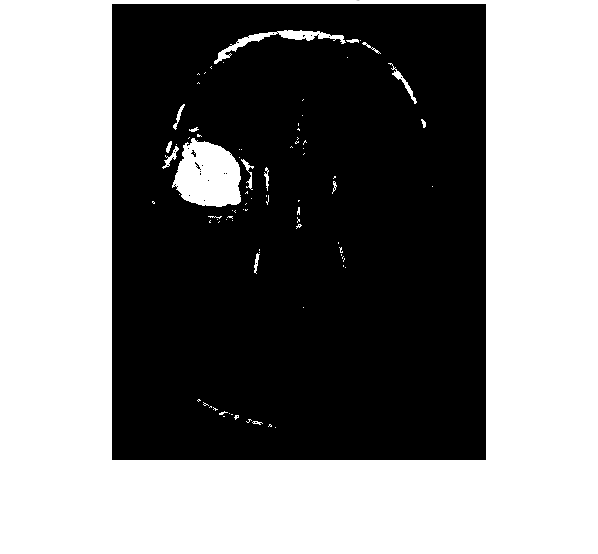

clusters = 4;
fuzzy_img = fuzzy_algo(ss_img, clusters, mask);
figure, imshow(fuzzy_img), title("Fuzzy C-Means Algorithm");

### Watershed Algorithm

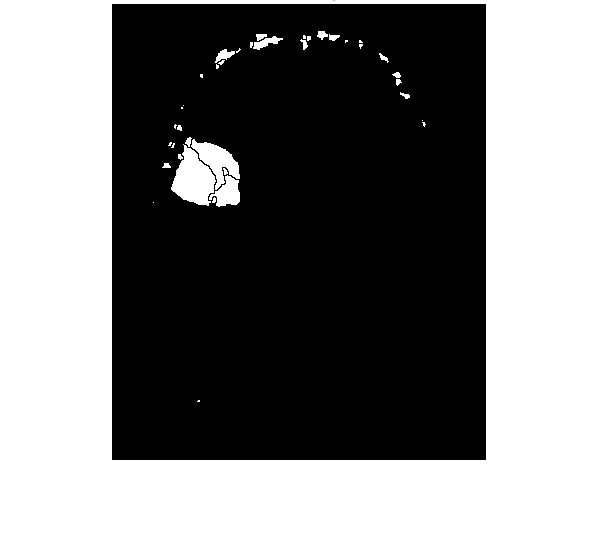

watershed_se = [0 1 0; 1 1 1; 0 1 0;];
[watershed_img, auto_percentage] = auto_watershed_algo(ss_img, imdilate(bitand(otsu_img, fuzzy_img), watershed_se), mask);
figure, imshow(watershed_img), title("Watershed Algorithm");

disp("The height threshold of minima to remove from the gradient image of the brain image is set to " + auto_percentage);

The height threshold of minima to remove from the gradient image of the brain image is set to 79


The higher the threshold, the greater the amount of shallow minima removed, resulting in less over-segmentation. Change the threshold levels if results are undesirable.

percentage = 79;
if percentage ~= 0
    watershed_img = watershed_algo(ss_img, imdilate(bitand(otsu_img, fuzzy_img), watershed_se), mask, percentage);
    figure, imshow(watershed_img), title("Watershed Algorithm");
end

## COMBINATION OF SEGMENTATION RESULTS

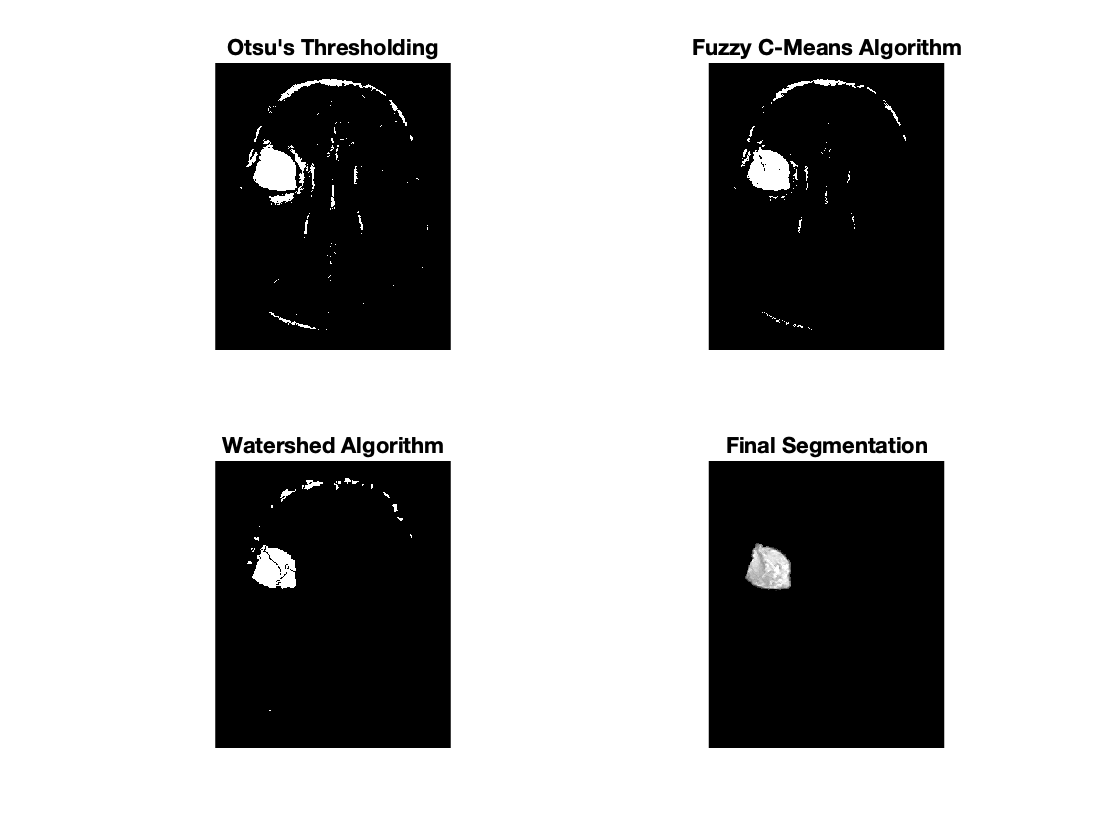

segment_mask = combine_results(otsu_img, watershed_img, fuzzy_img);
segmented_img = ss_img .* uint8(segment_mask);
figure,
subplot(2,2,1); imshow(otsu_img); title("Otsu's Thresholding");
subplot(2,2,2); imshow(fuzzy_img); title("Fuzzy C-Means Algorithm");
subplot(2,2,3); imshow(watershed_img); title("Watershed Algorithm");
subplot(2,2,4); imshow(segmented_img); title("Final Segmentation");

## MORPHOLOGICAL OPERATIONS

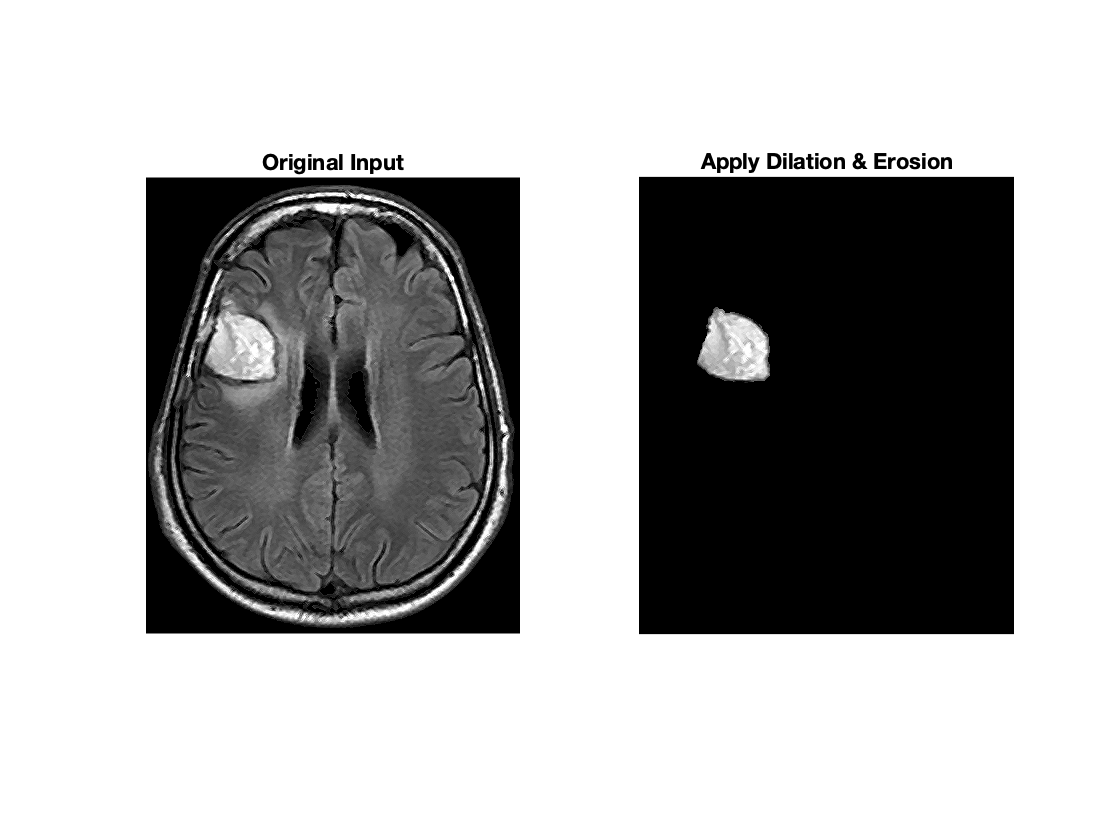

% dilation and erosion
morph_se = strel("square", 3);
morph_mask = imclose(segment_mask, morph_se);
morph_img = ss_img .* uint8(morph_mask);
figure,
subplot(1,2,1); imshow(img); title("Original Input");
subplot(1,2,2); imshow(morph_img); title("Apply Dilation & Erosion");

## FEATURE EXTRACTION 

% find GLCM of image
glcm = graycomatrix(morph_img);

% find contrast, correlation, entropy and standard deviation
glcm_contrast = struct2cell(graycoprops(glcm, 'contrast'));
glcm_correlation = struct2cell(graycoprops(glcm, 'correlation'));
glcm_entropy = num2cell(entropy(glcm));
glcm_sd = num2cell(std2(glcm));
img_features = cell2mat([glcm_contrast, glcm_correlation, glcm_entropy, glcm_sd]);

## DECISION TREE

% divide training set and data set
post_imgs = readtable("post_imgs_stats.xlsx");
[row, ~] = size(post_imgs);
post_train = post_imgs(1:round(0.7*row),:);
post_test = post_imgs(round(0.7*row)+1:row,:);

% train decision tree from features extracted
post_tree = fitctree([post_train(:, "CONTRAST"), post_train(:, "CORRELATION"), post_train(:, "ENTROPY"), post_train(:, "SD")], post_train(:, "TUMOUR"));

## CLASSIFICATION

% predict presence of tumour in brain image
img_pred = predict(post_tree, img_features);

% output final results
if img_pred == 1
    disp("This brain image has tumour(s).");
    [morph_mask_labels, tumour_count] = bwlabel(morph_mask);
    stats = regionprops(morph_mask_labels, 'Area');
    area = [stats.Area];
    disp("There is/are " + tumour_count + " tumour(s) detected.")
    disp("Area of tumour " + [1:tumour_count] + " is " + area + " pixels.");
elseif img_pred == 0
    disp("This brain image does not have any tumours.");
end

This brain image has tumour(s).


There is/are 1 tumour(s) detected.


Area of tumour 1 is 4225 pixels.
